realpole=true;
To=0;
Tend=20;
samples=1600;
Ts=Tend/samples;
n=10;

if realpole==true
    poles=[-3000 -2000 -250 -200 -50 -40 -0.1 -0.2 -0.01 -0.02];
else 
    poles=[-8+80j -8-80j -2+20j -2-20j -0.5+10j -0.5-10j -0.2+2j -0.2-2j -0.01+0.5j -0.01-0.5j];
end
% A=diag(poles);
% B=zeros(10,1);
% C=zeros(1,10);
D=0;
[A,B,C,D] = zp2ss([],poles,1)

A = 1.0e+03 *

   -5.0000   -2.4495         0         0         0         0         0         0         0         0
    2.4495         0         0         0         0         0         0         0         0         0
         0    0.0000   -0.4500   -0.2236         0         0         0         0         0         0
         0         0    0.2236         0         0         0         0         0         0         0
         0         0         0    0.0000   -0.0900   -0.0447         0         0         0         0
         0         0         0         0    0.0447         0         0         0         0         0
         0         0         0         0         0    0.0000   -0.0003   -0.0001         0         0
         0         0         0         0         0         0    0.0001         0         0         0
         0         0         0         0         0         0         0    0.0071   -0.0000   -0.0000
         0         0         0         0         0         0         0      

B =      1
     0
     0
     0
     0
     0
     0
     0
     0
     0


C =          0         0         0         0         0         0         0         0         0   70.7107


D = 0

csys=ss(A,B,C,D);


opt = c2dOptions('Method','Tustin');
dsys = c2d(csys,Ts,opt);
ev=eig(dsys.A)

ev =    -0.8987
   -0.8519
   -0.2195
   -0.1111
    0.5238
    0.6000
    0.9975
    0.9988
    0.9998
    0.9999


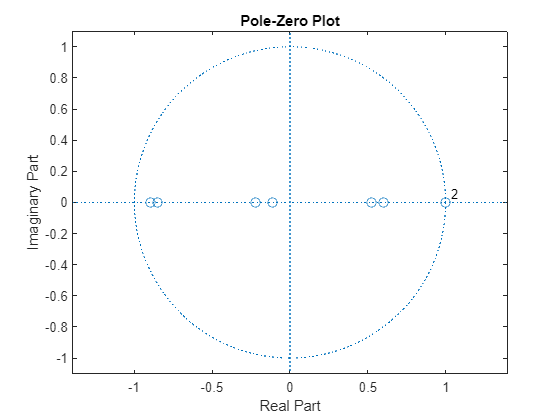

[y,tOut,x]=initial(dsys,10*ones(10,1),20);
zpole=pole(dsys);
zplane(zpole)

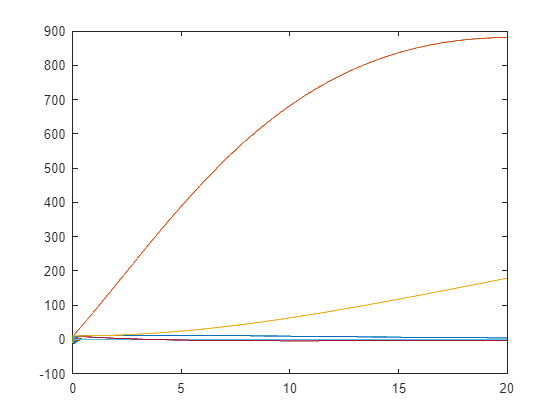

figure, plot(tOut,x)

if realpole==true
    writematrix(x','real_eig_timeseries.csv')
else
    writematrix(x','complex_eig_timeseries.csv')
end